clc; clear; close all;

% =========================================================
% Assignment2_Matlab_AG16
% Integrated script:
%   Section 2.1  Jacobian verification
%   Section 2.2  Gravity torque evaluation (workspace + farthest-piece task)
%
% DH convention:
%   [a_{i-1}, alpha_{i-1}, d_i, theta_i]
%   A_i = Rx(alpha_{i-1}) * Tx(a_{i-1}) * Rz(theta_i) * Tz(d_i)
% =========================================================

## -----------------------------

Robot constants (SI units)

## -----------------------------

b  = -0.025;
L1 = 0.05;
L2 = 0.22;
L3 = 0.18;
L4 = 0.10;
N  = 5;

## =========================================================

Section 2.1 - Jacobian verification (fast numeric)

## =========================================================

rng(16);
Ns = 120;          % random tests
h  = 1e-7;         % finite-difference step

err_max_each = zeros(Ns,1);
err_fro_each = zeros(Ns,1);

for k = 1:Ns
    q = [deg2rad(-180 + 360*rand);
         deg2rad(-90  + 180*rand);
         deg2rad(-120 + 240*rand);
         deg2rad(-120 + 240*rand);
         deg2rad(-180 + 360*rand)];

    Jg = jacobian_geometric(q, b, L1, L2, L3, L4);
    Jd = jacobian_differential_fd(q, b, L1, L2, L3, L4, h);

    E = Jg - Jd;
    err_max_each(k) = max(abs(E), [], 'all');
    err_fro_each(k) = norm(E, 'fro');
end

fprintf('\n================ Jacobian Verification (Section 2.1) ================\n');


================ Jacobian Verification (Section 2.1) ================


fprintf('Samples: %d, FD step: %.1e\n', Ns, h);

Samples: 120, FD step: 1.0e-07


fprintf('max over samples of max abs(Jg-Jd): %.3e\n', max(err_max_each));

max over samples of max abs(Jg-Jd): 2.684e-08


fprintf('mean of max abs(Jg-Jd): %.3e\n', mean(err_max_each));

mean of max abs(Jg-Jd): 2.177e-08


fprintf('max over samples of fro norm(Jg-Jd): %.3e\n', max(err_fro_each));

max over samples of fro norm(Jg-Jd): 6.316e-08


if max(err_max_each) < 1e-6
    fprintf('RESULT: PASS\n');
else
    fprintf('RESULT: CHECK REQUIRED\n');
end

RESULT: PASS


fprintf('=====================================================================\n');

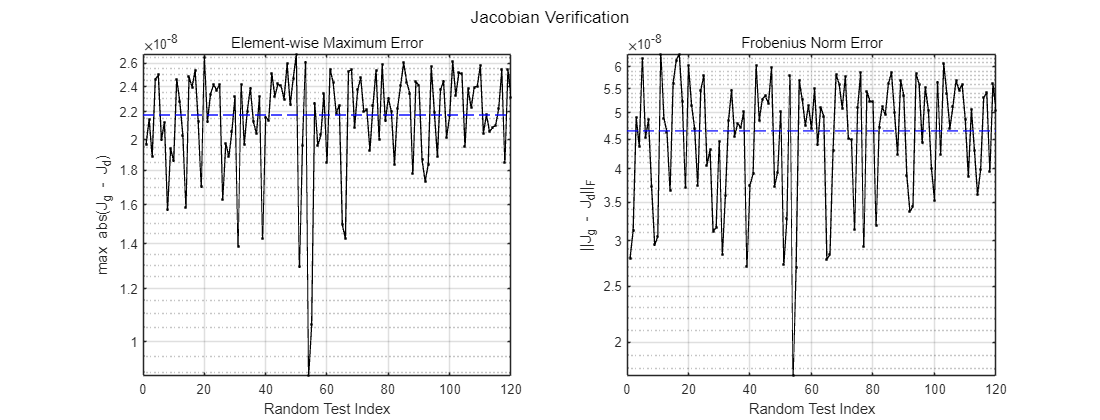


figJ = figure('Color','w','Position',[120 120 1100 420], 'Name','Jacobian Verification');
subplot(1,2,1);
semilogy(1:Ns, err_max_each, 'k.-', 'LineWidth', 1.0); hold on;
yline(mean(err_max_each), 'b--', 'LineWidth', 1.4);
grid on; xlabel('Random Test Index'); ylabel('max abs(J_g - J_d)');
title('Element-wise Maximum Error');

subplot(1,2,2);
semilogy(1:Ns, err_fro_each, 'k.-', 'LineWidth', 1.0); hold on;
yline(mean(err_fro_each), 'b--', 'LineWidth', 1.4);
grid on; xlabel('Random Test Index'); ylabel('||J_g - J_d||_F');
title('Frobenius Norm Error');

sgtitle('Jacobian Verification');
saveas(figJ, 'Jacobian_verification_result.png');

## =========================================================

Section 2.2 - Gravity torque evaluation

## =========================================================

## Link masses and COM (kg, m)

joints 1-4: STS3215 (55g), joint5 + gripper actuator: STS3045M (35g)

m = [0.073; 0.093; 0.083; 0.071; 0.049];

% pc_local(:,i): COM of link i in frame {i}
pc_local = [ ...
   -0.0247,  0.1750, 0.1500, 0.0000,  0.0000;
    0.0000,  0.0000, 0.0000, 0.0887,  0.0000;
    0.0000,  0.0000, 0.0000, 0.0000, -0.0100];

## Payload

m_payload = 0.060;   % kg (heaviest chess piece)

## Motor nominal torque (rated continuous @ 6V)

kgcm_to_Nm = 0.0980665;
tau_STS3215  = 6.5 * kgcm_to_Nm;   % 0.6374 N*m
tau_STS3045M = 2.0 * kgcm_to_Nm;   % 0.1961 N*m
% Case A: no gearbox
tau_nominal_base = [tau_STS3215; tau_STS3215; tau_STS3215; tau_STS3215; tau_STS3045M];
% Case B: Joint-2 with 3:1 gearbox
tau_nominal_gb3 = [tau_STS3215; 3*tau_STS3215; tau_STS3215; tau_STS3215; tau_STS3045M];

## Gravity

g0 = [0; 0; -9.81];

## Part A: full workspace scan

q1Range = deg2rad(linspace(-180, 180, 13));
q2Range = deg2rad(linspace(-90,   90,  9));
q3Range = deg2rad(linspace(-120, 120,  9));
q4Range = deg2rad(linspace(-120, 120,  9));
q5Range = deg2rad(linspace(-90,   90,  7));

numSamples = numel(q1Range)*numel(q2Range)*numel(q3Range)*numel(q4Range)*numel(q5Range);
fprintf('\nTotal samples: %d\n', numSamples);


Total samples: 66339



maxAbsTau_ws = zeros(N,1);
qAtMax_ws = zeros(N,N);

count = 0;
t0 = tic;
for q1 = q1Range
for q2 = q2Range
for q3 = q3Range
for q4 = q4Range
for q5 = q5Range
    q = [q1;q2;q3;q4;q5];
    tau_g = gravityTorqueAtQ(q, b, L1, L2, L3, L4, m, pc_local, m_payload, g0);

    for j = 1:N
        if abs(tau_g(j)) > maxAbsTau_ws(j)
            maxAbsTau_ws(j) = abs(tau_g(j));
            qAtMax_ws(:,j) = q;
        end
    end

    count = count + 1;
    if mod(count,5000)==0
        fprintf('Processed %d / %d\n', count, numSamples);
    end
end
end
end
end
end

Processed 5000 / 66339
Processed 10000 / 66339
Processed 15000 / 66339
Processed 20000 / 66339
Processed 25000 / 66339
Processed 30000 / 66339
Processed 35000 / 66339
Processed 40000 / 66339
Processed 45000 / 66339
Processed 50000 / 66339
Processed 55000 / 66339
Processed 60000 / 66339
Processed 65000 / 66339


t_ws = toc(t0);
margin_ws_base = tau_nominal_base - maxAbsTau_ws;
margin_ws_gb3  = tau_nominal_gb3  - maxAbsTau_ws;

## Part B: farthest-piece pick-and-place task (aligned with robot_chess_pick_place_sim)

board_x0   = 0.08;
board_y0   = 0.00;
board_cell = 0.05;
board_n    = 8;
z_board    = 0.00;
z_lift     = 0.08;

[P_pick, ~] = farthestBoardSquare(board_x0, board_y0, board_cell, board_n);
P_place = [0.305; 0.175; z_board];

P_pick_up  = [P_pick(1);  P_pick(2);  z_lift];
P_place_up = [P_place(1); P_place(2); z_lift];

q_home      = deg2rad([0;0;0;0;0]);
q_pick_up   = inverseKinematicsPosition(P_pick_up,  q_home,    b, L1, L2, L3, L4);
q_pick      = inverseKinematicsPosition(P_pick,     q_pick_up, b, L1, L2, L3, L4);
q_place_up  = inverseKinematicsPosition(P_place_up, q_pick,    b, L1, L2, L3, L4);
q_place     = inverseKinematicsPosition(P_place,    q_place_up,b, L1, L2, L3, L4);

q_pick_up  = nearestEquivalentToReference(q_pick_up,  q_home);
q_pick     = nearestEquivalentToReference(q_pick,     q_pick_up);
q_place_up = nearestEquivalentToReference(q_place_up, q_pick);
q_place    = nearestEquivalentToReference(q_place,    q_place_up);

N1 = 40; N2 = 25; N3 = 20; N4 = 25; N5 = 45; N6 = 25; N7 = 20; N8 = 25;
Q1 = jointTrajectory(q_home,     q_pick_up,  N1);
Q2 = jointTrajectory(q_pick_up,  q_pick,     N2);
Q3 = repmat(q_pick, 1, N3);
Q4 = jointTrajectory(q_pick,     q_pick_up,  N4);
Q5 = jointTrajectory(q_pick_up,  q_place_up, N5);
Q6 = jointTrajectory(q_place_up, q_place,    N6);
Q7 = repmat(q_place, 1, N7);
Q8 = jointTrajectory(q_place,    q_place_up, N8);

Q_task = [Q1 Q2 Q3 Q4 Q5 Q6 Q7 Q8];
Q_task = unwrapJointTrajectory(Q_task);

tau_task = zeros(N, size(Q_task,2));
for k = 1:size(Q_task,2)
    tau_task(:,k) = gravityTorqueAtQ(Q_task(:,k), b, L1, L2, L3, L4, m, pc_local, m_payload, g0);
end
maxAbsTau_task = max(abs(tau_task), [], 2);
margin_task_base = tau_nominal_base - maxAbsTau_task;
margin_task_gb3  = tau_nominal_gb3  - maxAbsTau_task;

## Console summary

fprintf('\n========== 2.2 Gravity Torque Results ==========\n');


========== 2.2 Gravity Torque Results ==========


fprintf('Processed (workspace): %d / %d (%.2f s)\n', count, numSamples, t_ws);

Processed (workspace): 66339 / 66339 (0.96 s)


fprintf('Farthest pick square center: [%.3f, %.3f, %.3f] m\n', P_pick(1), P_pick(2), P_pick(3));

Farthest pick square center: [0.455, -0.175, 0.000] m


fprintf('Task trajectory samples: %d\n', size(Q_task,2));

Task trajectory samples: 225



fprintf('\n[Workspace max]\n');


[Workspace max]


for j = 1:N
    fprintf('Joint %d: max|tau_g| = %.4f N*m at q = [%.1f %.1f %.1f %.1f %.1f] deg\n', ...
        j, maxAbsTau_ws(j), ...
        rad2deg(qAtMax_ws(1,j)), rad2deg(qAtMax_ws(2,j)), rad2deg(qAtMax_ws(3,j)), ...
        rad2deg(qAtMax_ws(4,j)), rad2deg(qAtMax_ws(5,j)));
end

Joint 1: max|tau_g| = 0.0000 N*m at q = [0.0 0.0 0.0 0.0 0.0] deg
Joint 2: max|tau_g| = 1.3311 N*m at q = [-180.0 -90.0 0.0 0.0 -90.0] deg
Joint 3: max|tau_g| = 0.6039 N*m at q = [-180.0 -90.0 0.0 0.0 -90.0] deg
Joint 4: max|tau_g| = 0.1639 N*m at q = [-180.0 -90.0 0.0 0.0 -90.0] deg
Joint 5: max|tau_g| = 0.0000 N*m at q = [-60.0 45.0 90.0 -60.0 -90.0] deg



fprintf('\n[Farthest-piece pick-and-place trajectory max]\n');


[Farthest-piece pick-and-place trajectory max]


for j = 1:N
    fprintf('Joint %d: max|tau_g| = %.4f N*m, tau_nom(base)=%.4f, margin(base)=%+0.4f, tau_nom(gb3)=%.4f, margin(gb3)=%+0.4f N*m\n', ...
        j, maxAbsTau_task(j), ...
        tau_nominal_base(j), margin_task_base(j), ...
        tau_nominal_gb3(j),  margin_task_gb3(j));
end

Joint 1: max|tau_g| = 0.0000 N*m, tau_nom(base)=0.6374, margin(base)=+0.6374, tau_nom(gb3)=0.6374, margin(gb3)=+0.6374 N*m
Joint 2: max|tau_g| = 1.2425 N*m, tau_nom(base)=0.6374, margin(base)=-0.6051, tau_nom(gb3)=1.9123, margin(gb3)=+0.6698 N*m
Joint 3: max|tau_g| = 0.6019 N*m, tau_nom(base)=0.6374, margin(base)=+0.0355, tau_nom(gb3)=0.6374, margin(gb3)=+0.0355 N*m
Joint 4: max|tau_g| = 0.1639 N*m, tau_nom(base)=0.6374, margin(base)=+0.4736, tau_nom(gb3)=0.6374, margin(gb3)=+0.4736 N*m
Joint 5: max|tau_g| = 0.0000 N*m, tau_nom(base)=0.1961, margin(base)=+0.1961, tau_nom(gb3)=0.1961, margin(gb3)=+0.1961 N*m



if any(margin_ws_base < 0)
    fprintf('\nWARNING (base): Workspace scan exceeds nominal torque on some joints.\n');
else
    fprintf('\nPASS (base): Workspace scan is within nominal torque.\n');
end


WARNING (base): Workspace scan exceeds nominal torque on some joints.



if any(margin_task_base < 0)
    fprintf('WARNING (base): Farthest-piece task trajectory exceeds nominal torque on some joints.\n');
else
    fprintf('PASS (base): Farthest-piece task trajectory is within nominal torque.\n');
end

WARNING (base): Farthest-piece task trajectory exceeds nominal torque on some joints.



if any(margin_ws_gb3 < 0)
    fprintf('WARNING (gb3): Workspace scan exceeds nominal torque on some joints.\n');
else
    fprintf('PASS (gb3): Workspace scan is within nominal torque.\n');
end

PASS (gb3): Workspace scan is within nominal torque.



if any(margin_task_gb3 < 0)
    fprintf('WARNING (gb3): Farthest-piece task trajectory exceeds nominal torque on some joints.\n');
else
    fprintf('PASS (gb3): Farthest-piece task trajectory is within nominal torque.\n');
end

PASS (gb3): Farthest-piece task trajectory is within nominal torque.


## Save numeric outputs

T_ws = table((1:N)', maxAbsTau_ws, ...
    tau_nominal_base, margin_ws_base, ...
    tau_nominal_gb3,  margin_ws_gb3, ...
    'VariableNames', {'Joint','TauRequiredMax_WS_Nm', ...
    'TauNominal_Base_Nm','Margin_WS_Base_Nm', ...
    'TauNominal_GB3_Nm','Margin_WS_GB3_Nm'});
writetable(T_ws, 'Section22_torque_summary_workspace.csv');

T_task = table((1:N)', maxAbsTau_task, ...
    tau_nominal_base, margin_task_base, ...
    tau_nominal_gb3,  margin_task_gb3, ...
    'VariableNames', {'Joint','TauRequiredMax_FarthestTask_Nm', ...
    'TauNominal_Base_Nm','Margin_FarthestTask_Base_Nm', ...
    'TauNominal_GB3_Nm','Margin_FarthestTask_GB3_Nm'});
writetable(T_task, 'Section22_torque_summary_farthest_task.csv');

## Report figure (without workspace-max bar series)

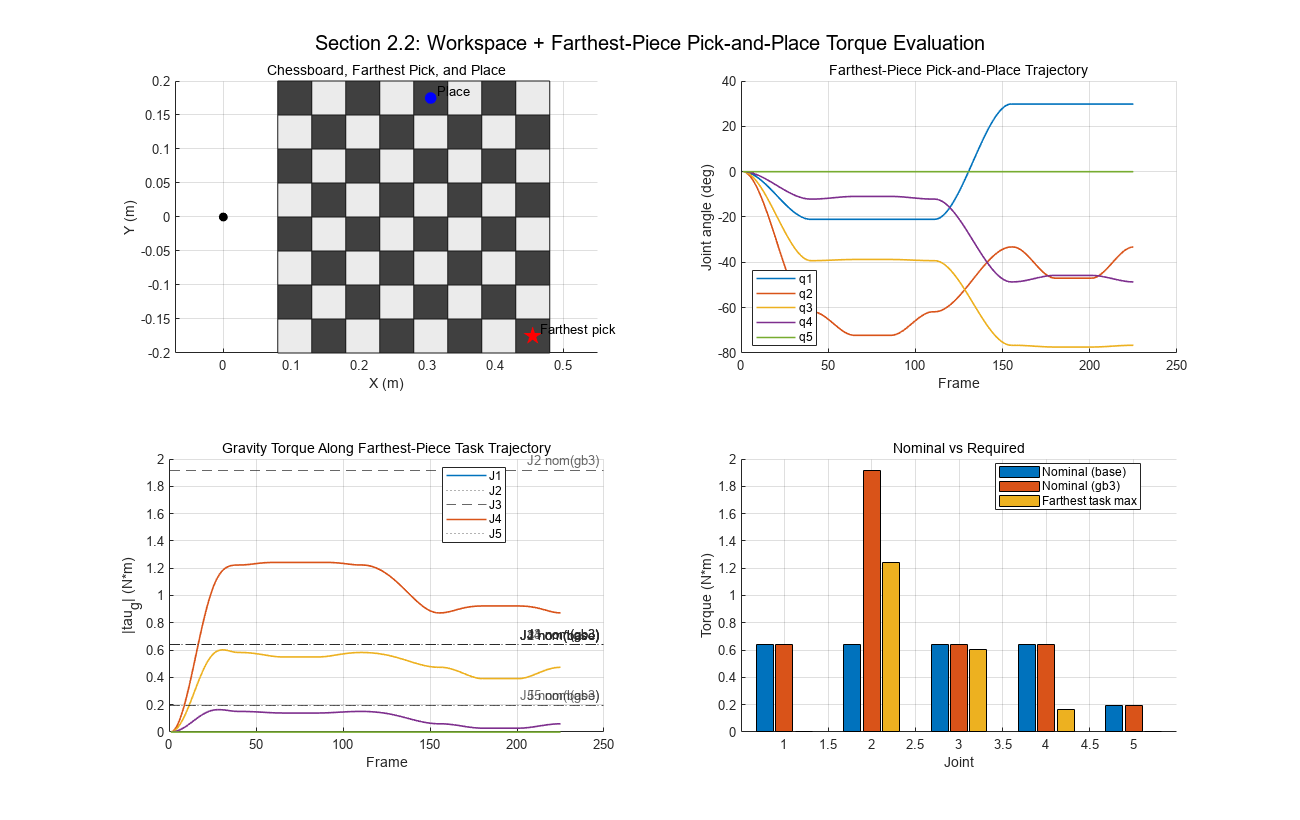

figT = figure('Color','w','Position',[90 90 1300 820]);

subplot(2,2,1); hold on; axis equal; grid on;
drawBoardTop(board_x0, board_y0, board_cell, board_n);
plot(0, 0, 'ko', 'MarkerFaceColor','k', 'MarkerSize', 6);
plot(P_pick(1), P_pick(2), 'rp', 'MarkerSize', 12, 'MarkerFaceColor','r');
plot(P_place(1), P_place(2), 'bo', 'MarkerSize', 8, 'MarkerFaceColor','b');
text(P_pick(1)+0.01, P_pick(2)+0.01, 'Farthest pick', 'FontSize', 10);
text(P_place(1)+0.01, P_place(2)+0.01, 'Place', 'FontSize', 10);
xlabel('X (m)'); ylabel('Y (m)');
title('Chessboard, Farthest Pick, and Place');

subplot(2,2,2); hold on; grid on;
plot(rad2deg(Q_task(1,:)), 'LineWidth', 1.2);
plot(rad2deg(Q_task(2,:)), 'LineWidth', 1.2);
plot(rad2deg(Q_task(3,:)), 'LineWidth', 1.2);
plot(rad2deg(Q_task(4,:)), 'LineWidth', 1.2);
plot(rad2deg(Q_task(5,:)), 'LineWidth', 1.2);
xlabel('Frame'); ylabel('Joint angle (deg)');
title('Farthest-Piece Pick-and-Place Trajectory');
legend('q1','q2','q3','q4','q5','Location','best');

subplot(2,2,3); hold on; grid on;
for j = 1:N
    plot(abs(tau_task(j,:)), 'LineWidth', 1.2);
    yline(tau_nominal_base(j), ':', sprintf('J%d nom(base)',j), 'LineWidth', 0.7);
    yline(tau_nominal_gb3(j), '--', sprintf('J%d nom(gb3)',j), 'LineWidth', 0.8);
end
xlabel('Frame'); ylabel('|tau_g| (N*m)');
title('Gravity Torque Along Farthest-Piece Task Trajectory');
legend('J1','J2','J3','J4','J5','Location','best');

subplot(2,2,4); hold on; grid on;
bar(1:N, [tau_nominal_base, tau_nominal_gb3, maxAbsTau_task], 0.88);
xlabel('Joint'); ylabel('Torque (N*m)');
title('Nominal vs Required');
legend('Nominal (base)','Nominal (gb3)','Farthest task max','Location','best');

sgtitle('Section 2.2: Workspace + Farthest-Piece Pick-and-Place Torque Evaluation');
saveas(figT, 'Section22_farthest_piece_task_evaluation.png');

## =========================================================

Local functions

## =========================================================

function tau_g = gravityTorqueAtQ(q, b, L1, L2, L3, L4, m, pc_local, m_payload, g0)
    N = 5;
    [T_all, o, z] = fk_all(q, b, L1, L2, L3, L4);
    oE = o(:,5);
    tau_g = zeros(N,1);

    for i = 1:N
        Ri = T_all(1:3,1:3,i);
        p_ci = Ri * pc_local(:,i) + o(:,i);
        Jv_ci = jacobian_point_on_link(i, p_ci, o, z);
        tau_g = tau_g + Jv_ci' * (m(i) * g0);
    end

    Jv_E = jacobian_point_general(oE, o, z);
    tau_g = tau_g + Jv_E' * (m_payload * g0);
end

function [P_far, P_all] = farthestBoardSquare(board_x0, board_y0, board_cell, board_n)
    xCenters = board_x0 + board_cell/2 + (0:board_n-1)*board_cell;
    yStart = board_y0 - board_n*board_cell/2;
    yCenters = yStart + board_cell/2 + (0:board_n-1)*board_cell;

    P_all = zeros(3, board_n*board_n);
    k = 1;
    for ix = 1:board_n
        for iy = 1:board_n
            P_all(:,k) = [xCenters(ix); yCenters(iy); 0];
            k = k + 1;
        end
    end

    dist = sqrt(P_all(1,:).^2 + P_all(2,:).^2);
    [~, idx] = max(dist);
    P_far = P_all(:,idx);
end

function q = inverseKinematicsPosition(pE, q_ref, b, L1, L2, L3, L4)
    q = q_ref;
    q(5) = 0;

    max_iters = 220;
    tol = 1e-4;
    lambda = 1e-2;
    step_limit = deg2rad(12);
    eps_val = 1e-6;

    for iter = 1:max_iters
        [~, o, ~] = fk_all(q, b, L1, L2, L3, L4);
        p_now = o(:,5);
        err = pE - p_now;
        if norm(err) < tol
            break;
        end

        J = zeros(3,4);
        for j = 1:4
            q_test = q;
            q_test(j) = q_test(j) + eps_val;
            [~, o_test, ~] = fk_all(q_test, b, L1, L2, L3, L4);
            p_test = o_test(:,5);
            J(:,j) = (p_test - p_now) / eps_val;
        end

        dq = J' * ((J*J' + lambda^2*eye(3)) \ err);
        dq = max(min(dq, step_limit), -step_limit);
        q(1:4) = q(1:4) + dq;
        q = nearestEquivalentToReference(q, q_ref);
        q(5) = 0;
    end

    [~, o_end, ~] = fk_all(q, b, L1, L2, L3, L4);
    final_err = norm(pE - o_end(:,5));
    if final_err > 5e-3
        error('IK did not converge to target. Final position error = %.6f m', final_err);
    end
end

function J = jacobian_geometric(q, b, L1, L2, L3, L4)
    [~, o, z] = fk_all(q, b, L1, L2, L3, L4);
    oE = o(:,5);

    Jv = zeros(3,5);
    Jw = zeros(3,5);
    for i = 1:5
        Jv(:,i) = cross(z(:,i), oE - o(:,i));
        Jw(:,i) = z(:,i);
    end
    J = [Jv; Jw];
end

function J = jacobian_differential_fd(q, b, L1, L2, L3, L4, h)
    T = fk_ee(q, b, L1, L2, L3, L4);
    p = T(1:3,4);
    R = T(1:3,1:3);

    Jv = zeros(3,5);
    Jw = zeros(3,5);

    for i = 1:5
        q2 = q;
        q2(i) = q2(i) + h;
        T2 = fk_ee(q2, b, L1, L2, L3, L4);
        p2 = T2(1:3,4);
        R2 = T2(1:3,1:3);

        Jv(:,i) = (p2 - p) / h;
        Rdot = (R2 - R) / h;
        Omega = Rdot * R.';
        Jw(:,i) = [Omega(3,2); Omega(1,3); Omega(2,1)];
    end
    J = [Jv; Jw];
end

function [T_all, o, z] = fk_all(q, b, L1, L2, L3, L4)
    A1 = dhTransform(0,   0,      L1, q(1));
    A2 = dhTransform(-b,  pi/2,   0,  q(2) + pi/2);
    A3 = dhTransform(L2,  0,      0,  q(3));
    A4 = dhTransform(L3,  0,      0,  q(4) - pi/2);
    A5 = dhTransform(0,  -pi/2,   L4, q(5));

    A = cat(3,A1,A2,A3,A4,A5);
    T = eye(4);
    T_all = zeros(4,4,5);
    o = zeros(3,5);
    z = zeros(3,5);

    for j = 1:5
        T = T * A(:,:,j);
        T_all(:,:,j) = T;
        o(:,j) = T(1:3,4);
        z(:,j) = T(1:3,3);
    end
end

function T = fk_ee(q, b, L1, L2, L3, L4)
    A1 = dhTransform(0,   0,      L1, q(1));
    A2 = dhTransform(-b,  pi/2,   0,  q(2) + pi/2);
    A3 = dhTransform(L2,  0,      0,  q(3));
    A4 = dhTransform(L3,  0,      0,  q(4) - pi/2);
    A5 = dhTransform(0,  -pi/2,   L4, q(5));
    T = A1*A2*A3*A4*A5;
end

function Jv = jacobian_point_on_link(i, p, o, z)
    N = 5;
    Jv = zeros(3,N);
    for j = 1:N
        if j <= i
            Jv(:,j) = cross(z(:,j), p - o(:,j));
        else
            Jv(:,j) = [0;0;0];
        end
    end
end

function Jv = jacobian_point_general(p, o, z)
    N = 5;
    Jv = zeros(3,N);
    for j = 1:N
        Jv(:,j) = cross(z(:,j), p - o(:,j));
    end
end

function A = dhTransform(a, alpha, d, theta)
    ca = cos(alpha); sa = sin(alpha);
    ct = cos(theta); st = sin(theta);
    A = [ct,    -st,      0,   a;
         st*ca, ct*ca,   -sa, -d*sa;
         st*sa, ct*sa,    ca,  d*ca;
         0,      0,       0,   1];
end

function q_adj = nearestEquivalentToReference(q, q_ref)
    q_adj = q;
    for i = 1:numel(q)
        delta = q_adj(i) - q_ref(i);
        q_adj(i) = q_adj(i) - 2*pi*round(delta/(2*pi));
    end
end

function Q_unwrapped = unwrapJointTrajectory(Q)
    Q_unwrapped = Q;
    for k = 2:size(Q,2)
        for j = 1:size(Q,1)
            delta = Q_unwrapped(j,k) - Q_unwrapped(j,k-1);
            Q_unwrapped(j,k) = Q_unwrapped(j,k) - 2*pi*round(delta/(2*pi));
        end
    end
end

function Q = jointTrajectory(q_start, q_end, Npts)
    Q = zeros(numel(q_start), Npts);
    for i = 1:Npts
        t = (i-1)/(Npts-1);
        s = 3*t^2 - 2*t^3;
        Q(:,i) = (1-s)*q_start + s*q_end;
    end
end

function drawBoardTop(board_x0, board_y0, board_cell, board_n)
    yStart = board_y0 - board_n*board_cell/2;
    for i = 0:board_n-1
        for j = 0:board_n-1
            x1 = board_x0 + i*board_cell;
            y1 = yStart + j*board_cell;
            X = [x1, x1+board_cell, x1+board_cell, x1];
            Y = [y1, y1, y1+board_cell, y1+board_cell];
            if mod(i+j,2)==0
                c = [0.92 0.92 0.92];
            else
                c = [0.25 0.25 0.25];
            end
            patch(X, Y, c, 'EdgeColor', [0.1 0.1 0.1]);
        end
    end
end